## Name:

## Date:

## PID: 

# Assignment 4 : Numerical Integration

**General Instructions:** Complete each question to the best of your abilities.  Include comments in your code to explain your thought process while answering.

Question 1 (15%): 

For function:


$$y=\ln \left(x\right)+\sin \left(3x\right)$$


a) (5%) Find the derivative using forward finite differences with a $h=0\ldotp 01$ from $x=0\ldotp 5$ to $6$.

clear,clc,close all

% % Step 1 
h = 0.01 ;% Step size
x = 0.5:h:6; % t_n

% Define the functiona
y=@(x) log(x)+sin(3*x);
df=@(x) 1./x + 3*cos(3*x); % exact derivative, for comparison

% % Step 2
dFForward=diff(y(x))./diff(x)

dFForward =     2.1476    2.0192    1.8922    1.7666    1.6424    1.5197    1.3983    1.2784    1.1600    1.0430    0.9276    0.8137    0.7015    0.5908    0.4818    0.3746    0.2690    0.1653    0.0634   -0.0366   -0.1347   -0.2308   -0.3249   -0.4170   -0.5069   -0.5947   -0.6803   -0.7637   -0.8448   -0.9236   -1.0000   -1.0740   -1.1456   -1.2147   -1.2812   -1.3453   -1.4067   -1.4656   -1.5217   -1.5752   -1.6261   -1.6741   -1.7195   -1.7620   -1.8018   -1.8387   -1.8729   -1.9041   -1.9326   -1.9581


b) (5%) Find the derivative using central finite differences with a $h=0\ldotp 01$ from $x=0$.5 to $6$.

% Method - Gradient
dFCentral=gradient(y(x),x);

c) (5%) Plot the result from (a), (b), and the analytically found derivative in a 1 by 3 plot (1 row 3 columns) using [subplot](https://www.mathworks.com/help/matlab/ref/subplot.html).

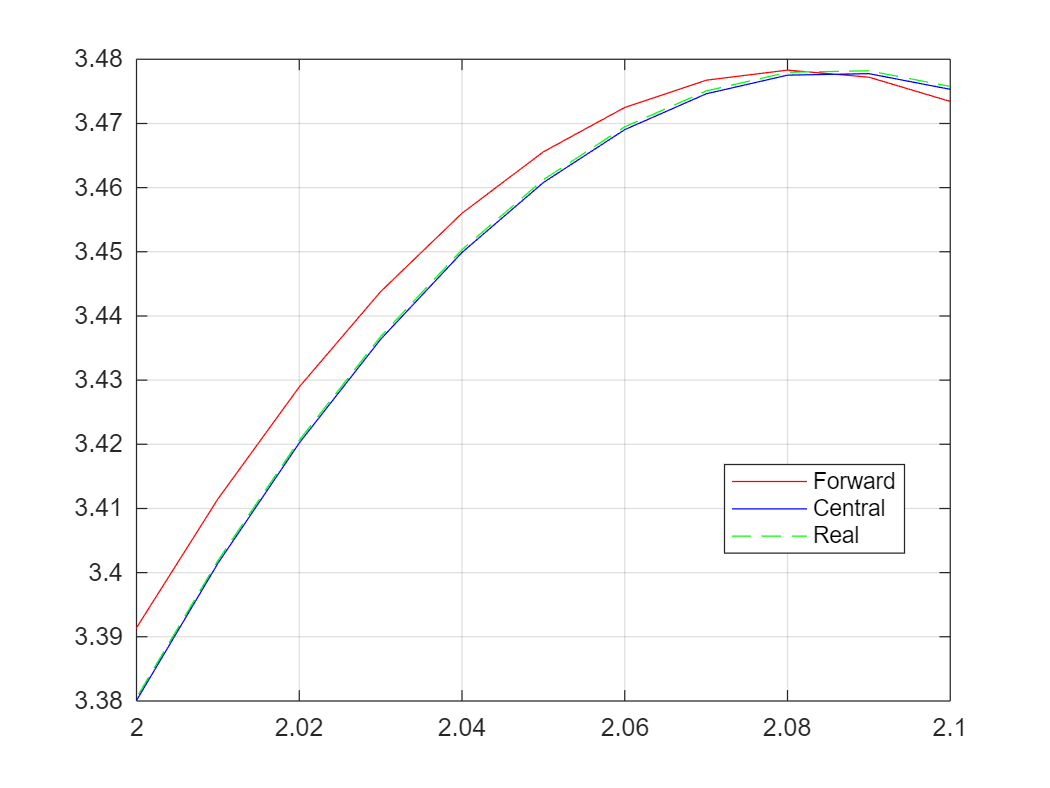

figure
plot(x(1:end-1),dFForward,'r')
hold on
plot(x,dFCentral,'b') 
plot(x,df(x),'--g')
legend('Forward','Central','Real', 'Location','best')
xlim([2 2.1])
grid on

Question 2 (25%): 

a) (10%) Solve and plot the following ordinary differential equation using the Forward Euler’s Method

$\frac{dy}{dt}=y-2y^2$ , y(0) = 2

from $t=0$ to $t=3$ using a step size of $h=0\ldotp 1\ldotp$ Also, plot the true analytical solution (either solve by hand or use online resources such as Wolfram Alpha, Symbolab, etc) and include labels and a legend.

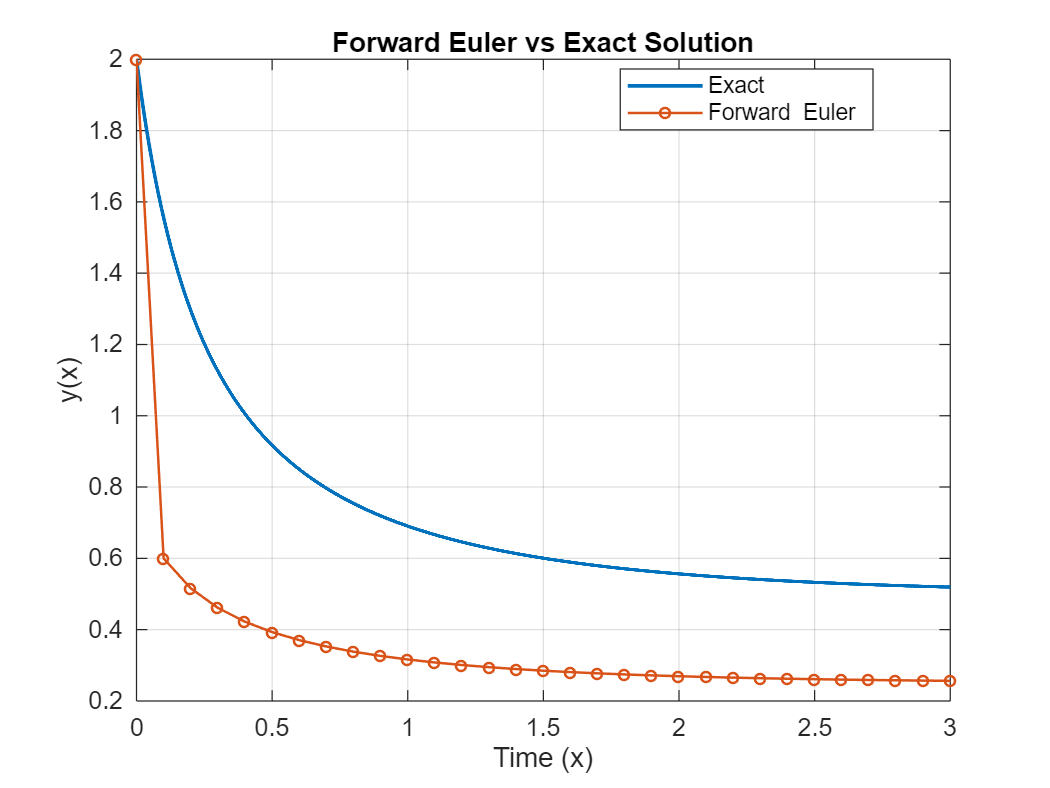

% % Step 1 
h = 0.1 ;% Step size
x = 0:h:3; % t_n
y0= 2;


% % Step 2
f = @(t,y) y- 4*y.^2 ; % fowards
df = @(t) 2*exp(t)./(4*exp(t)-3); % exact

% % Step 2
t = zeros(1,length(x)); % >> y_n
t(1) = y0;
for ii = 1:length(x)-1
    t(ii+1) = t(ii) + h * f(x(ii),t(ii));
    % Basically:  y_n+1 = y_n + h * f(t_n, y_n)
    %    where                       ^x(ii) is t_n
end

% % Step 3
figure;
tt = linspace(min(x), max(x), 10000); % smooth for exact solution
plot(tt, df(tt), 'LineWidth', 1.5) % exact
hold on;
plot(x, t, '-o', 'MarkerSize', 4, 'LineWidth', 1) % fowards
hold off;
xlabel('Time (x)');
ylabel('y(x)');
legend('Exact', 'Forward  Euler', 'Location', 'best');
title('Forward Euler vs Exact Solution');
grid on;

b) (5%) Show the absolute error of the above approximation for y(2).

% % Step 5
x_eval = 2;                                  % time to evaluate error
idx = find(abs(x - x_eval) < 1e-12, 1);      % index closest to x = 2
err_FE = abs(t(idx) - df(x_eval));           % absolute error
fprintf('Forward Euler absolute error at x = %.2f: %.6e\n',x_eval, err_FE);

Forward Euler absolute error at x = 2.00: 2.871436e-01


c) (10%) Plot the convergence from h =${10}^{-4}$ to h =${10}^{-2}$ for y(2).

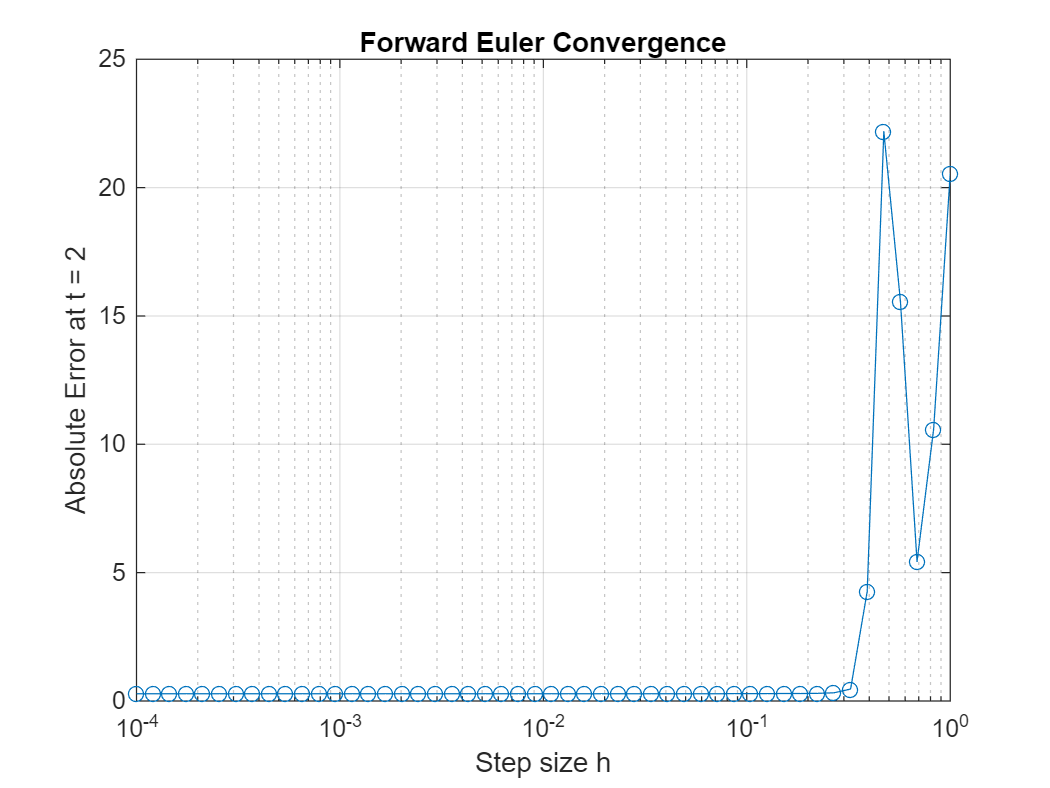

% % Step 1
h_values = logspace(-4,0); % step size


% % Step 2
y_true = @(t) 2*exp(t)./(4*exp(t)-3);
y_exact = y_true(2);



% % Step 3
%Need two loops !!
errors_forward = zeros(size(h_values));
t_end = 2; % we stop at y(2) aka t=2

for ii = 1:length(h_values)               %<<< LOOP 1
    h = h_values(ii);    % Current h
    t = 0:h:t_end;      % Time vector

    y_forward = zeros(1, length(t)); % pre-allo for loop 2
    y_forward(1) = 1; % initial for loop 2

    for jj = 1:length(t)-1                %<<< LOOP 2
        y_forward(jj+1) = y_forward(jj) + h * f(t(jj),y_forward(jj)); % forwards
    end
    errors_forward(ii) = abs(y_exact - y_forward(end));  % absolute errors at t = 2
end

% % Step 4
figure; % had to do it this way because the graph woudl not appear with just " figure" 
semilogx(h_values, errors_forward, '-o');
xlabel('Step size h');
ylabel('Absolute Error at t = 2');
title('Forward Euler Convergence');
grid on;

Question  3 (20%): 

a) (10%) Solve the following ordinary differential equation using the Backward Euler’s Method.

$\frac{dy}{dt}=-y^3$, y(0)=1

from t=0 to t=3 using a step size of h=0.1

b) (10%) Find the analytical solution (either solve by hand or use online resources such as Wolfram Alpha, Symbolab, etc) and plot it against the result from (a).

Question 4(15%)

For the following system:


$$\begin{array}{c}
\frac{dy_{{\left(1\right)}} }{dt}=y_{{\left(1\right)}} +5y_{{\left(2\right)}} \\
\frac{dy_{{\left(2\right)}} }{dt}={3y}_{{\left(1\right)}} \;\;-y_{{\left(2\right)}} 
\end{array}$$



$$y_{{\left(1\right)}} {\left(0\right)}=2,y_{{\left(2\right)}} {\left(0\right)}=3$$


a) (10%) Solve the system of differential equations and plot it from 0 to 3.

b) (5%) Find the value at $Y{\left(2\ldotp 5\right)}={\left[\begin{array}{c}
?\\
?
\end{array}\right]}$.

Question 5 (25%)

Constrained population growth of bacteria and amoebae is governed by the following:

- The amoebae will decrease by 150% if left undisturbed.

- The bacteria will increase by 80% if left undisturbed. 

- The amoebae will eat the bacteria reducing their, the bacteria's, numbers by 30%.

- The amoebae will increase by 20% when bacteria are present.

a) (20%) Model the system by converting the above statements into differential equations, one for amoebae and another for bacteria. Then, solve and plot it over 4 hours. The initial amount of bacteria is 5 billion and of amoebae is 1 billion. Use a step size of 0.01.

b) (5%) Find the time when the bacteria population is at its maximum.